# ASE387P Homework 3

## Problem 1

clear; clc

### Part a-b

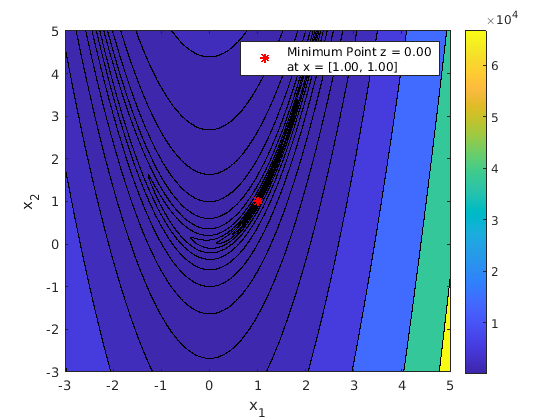

f = @(x) (1-x(1))^2 + 100*(x(2)-x(1)^2)^2;
del = 0.01;
x1 = -3:del:5;
x2 = -3:del:5;
z = zeros(length(x1));
for i = 1:length(x1)
    for j = 1:length(x1)
        z(j, i) = f([x1(i), x2(j)]); 
    end
end
contourf(x1, x2, z, [logspace(-4, 5, 22), max(max(z))*0.85], 'HandleVisibility',"off")
colorbar
[val, idx1] = min(z);
[val, idx2] = min(val);
idx1 = idx1(idx2);
hold on
scatter(x1(idx2), x2(idx1), 'r*', 'DisplayName', ...
    sprintf('Minimum Point z = %0.2f \nat x = [%0.2f, %0.2f]', val, x1(idx2), x2(idx1)), ...
    'linewidth', 1.5)
legend
hold off
xlabel('x_1'); ylabel('x_2')

% exportgraphics(gcf, 'hw3p1a.png', 'Resolution', 200)

### Part c

syms x_1 x_2
f_sym = (1-x_1)^2 + 100*(x_2-x_1^2)^2

$$f\_sym = {\left(x_{1}-1\right)}^{2}+100\,{\left(x_{2}-{x_{1}}^{2}\right)}^{2}$$

eqs = [diff(f_sym, x_1) == 0; diff(f_sym, x_2) == 0]

$$eqs = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2=0\\ 200\,x_{2}-200\,{x_{1}}^{2}=0 \end{array}\right)$$

sol = solve(eqs); fprintf('Derivatives = 0 \nat x = [%0.2f, %0.2f]', sol.x_1, sol.x_2)

Derivatives = 0 
at x = [1.00, 1.00]

#### 2nd Order Necessary and Sufficient Condition

Necessary: $\nabla f(x_\ast) = \vec{0}$

Sufficient: $\nabla^2f(x_\ast)$ is positive definite

grad = [diff(f_sym, x_1); diff(f_sym, x_2)]

$$grad = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2\\ 200\,x_{2}-200\,{x_{1}}^{2} \end{array}\right)$$

f_grad_ = matlabFunction(grad);
fprintf('Norm of the first gradient of f is %0.2f,\n thus the necessary condition is satisfied', norm(f_grad_(sol.x_1, sol.x_2)))

Norm of the first gradient of f is 0.00,
 thus the necessary condition is satisfied

grad = [diff(grad(1), x_1) diff(grad(1), x_2);
    diff(grad(2), x_1) diff(grad(2), x_2)]

$$grad = \left(\begin{array}{cc} 1200\,{x_{1}}^{2}-400\,x_{2}+2 & -400\,x_{1}\\ -400\,x_{1} & 200 \end{array}\right)$$

f_grad2_ = matlabFunction(grad);
[A, flag] = chol(f_grad2_(sol.x_1, sol.x_2))

$$A = \left(\begin{array}{cc} \sqrt{802} & -\frac{200\,\sqrt{802}}{401}\\ 0 & \frac{10\,\sqrt{2}\,\sqrt{401}}{401} \end{array}\right)$$

flag = 0

fprintf('As the Cholesky factorization was successful, and returned a flag of %i\n the sufficient condition was satisfied', flag)

As the Cholesky factorization was successful, and returned a flag of 0
 the sufficient condition was satisfied

## Problem 2

% SETUP
s = [-1 1].';
x0 = [4 -1].';
t0 = 0.1;
f_grad = @(x) f_grad_(x(1), x(2));
f_grad2 = @(x) f_grad2_(x(1), x(2));

% BRACKETING MINIMUM
[pts, line, iters] = lineSearch(x0, s, f, t0, 4, 2)

pts = 1×3 struct array with fields:
    x
    z


line =     4.0000    3.9000    3.8000    3.7000    3.5000    3.3000    3.1000    2.9000    2.5000    2.1000    1.7000    1.3000    0.5000
   -1.0000   -0.9000   -0.8000   -0.7000   -0.5000   -0.3000   -0.1000    0.1000    0.5000    0.9000    1.3000    1.7000    2.5000


iters = 13



% QUADRATIC POLYNOMIAL LINE SEARCH
[x_min_quad, z_min_quad, iter_quad] = quadMin([pts(:).x], [pts(:).z], s, f, f_grad, f_grad2)

x_min_quad =     1.3025
    1.6975


z_min_quad = 0.0916

iter_quad = 3


% GOLDEN RATIO LINE SEARCH
[x_min_gr, z_min_gr, iter_gr, allX] = grMin([pts(:).x], [pts(:).z], s, f)

x_min_gr =     1.3025
    1.6975


z_min_gr = 0.0916

iter_gr = 35

allX =     1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3025    1.3026    1.3025    1.3025    1.3026    1.3025    1.3024    1.3026    1.3023    1.3028    1.3019    1.3034    1.3011    1.3048    1.3025    1.2927    1.2988    1.3243    1.2830    1.3498    1.3085    1.1334    1.4167    1.7000    1.2416    0.9584    0.5000
    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6975    1.6974    1.6975    1.6975    1.6974    1.6975    1.6976    1.6974    1.6977    1.6972    1.6981    1.6966    1.6989    1.6952    1.6975    1.7073    1.7012    1.6757    1.7170    1.6502    1.6915    1.8666    1.5833    1.3000    1.7584    2.0416    2.5000


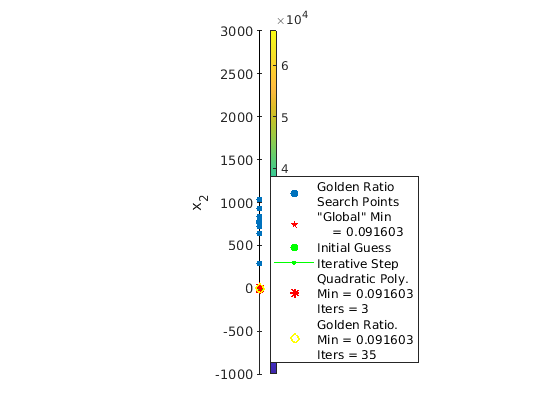


% PLOTTING
contourf(x1, x2, z, [logspace(-4, 5, 22), max(max(z))*0.85], 'HandleVisibility',"off")
colorbar
[val, idx1] = min(z);
[val, idx2] = min(val);
idx1 = idx1(idx2);
hold on
% scatter(x1(idx2), x2(idx1), 'r*', 'DisplayName', ...
%     sprintf('Minimum Point z = %0.2f \nat x = [%0.2f, %0.2f]', val, x1(idx2), x2(idx1)), ...
%     'linewidth', 1.5)
scatter(line(1, 1), line(2, 1), 'go', 'filled', 'DisplayName', 'Initial Guess')
plot(line(1, :), line(2, :), 'g.-', 'DisplayName', 'Iterative Step')
scatter(x_min_quad(1), x_min_quad(2), 'r*', 'DisplayName', ...
    sprintf('Quadratic Poly.\nMin = %0.6f\nIters = %i', z_min_quad, iter_quad), ...
    'linewidth', 1.5)
scatter(x_min_gr(1), x_min_gr(2), 'yo', 'DisplayName', ...
    sprintf('Golden Ratio.\nMin = %0.6f\nIters = %i', z_min_gr, iter_gr), ...
    'linewidth', 1.5)
lgn = legend; lgn.Location = 'southwest';
axis equal
hold off
xlabel('x_1'); ylabel('x_2')

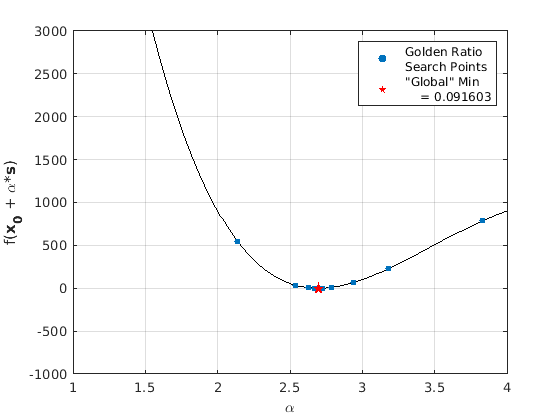

% exportgraphics(gcf, 'hw3p2.png', 'Resolution', 200)

% ADDITIONAL PLOT
line = linspace(0, 7, 50000);
y = zeros(length(line), 1);
for i = 1:length(y); y(i) = f(x0 + line(i).*s); end
plot(line(1:50:end), y(1:50:end), 'k-', 'HandleVisibility', "off")
hold on
[val, idx] = min(y);
ylim([-1000 3000])
legend
ylabel('f({\bfx_0} + \alpha*{\bfs})', "Interpreter","tex")
xlabel('\alpha')
dist = zeros(size(allX, 2), 1); ydist = dist;
for i = 1:size(allX, 2)
    dist(i) = norm(allX(:, i)-x0)-1.1173;
    ydist(i) = f(x0 + dist(i).*s);%*1.85;
end
scatter(dist, ydist, 20, 'o', 'filled', 'MarkerFaceColor', [0 0.4470  0.7410],...
    'DisplayName', sprintf('Golden Ratio \nSearch Points'))
scatter(line(idx), y(idx), 100, 'rp', 'filled',...
    'DisplayName', sprintf('"Global" Min\n    = %0.6f', val))
xlim([1 4])
grid on


% CREATING TABLE OF RESULTS
% tMult = [1.1 1.25 1.5 2 2.5 3 5];
% tSteps = [2 4 8 16];
% C = cell(length(tSteps), length(tMult));
% for i = 1:length(tSteps)
%     for j = 1:length(tMult)
%         % FINDING ITERATIONS
%         [pts, ~, iters_line] = lineSearch(x0, s, f, t0, tSteps(i), tMult(j));
%         [~, ~, iter_quad] = quadMin([pts(:).x], [pts(:).z], s, f, f_grad, f_grad2);
%         [~, ~, iter_gr] = grMin([pts(:).x], [pts(:).z], s, f);
%         
%         % COLLECTING
%         C{i, j} = [iters_line, iter_quad, iter_gr];
%     end
% end
% C = cat(2, num2cell(tSteps.'), C);
% colNames = {'NumSteps', '1.1 Multiplier', '1.25 Multiplier', '1.5 Multiplier', '2.0 Multiplier', '2.5 Multiplier', '3.0 Multiplier', '5.0 Multiplier'};
% rowNames = {'2 Steps', '4 Steps', '8 Steps', '16 Steps'};
% dimNames = ["Num Steps","Multiplier"];
% T = cell2table(C(:, 2:end), 'DimensionNames', dimNames, 'VariableNames', colNames(2:end), 'RowNames', rowNames)

function [pts, x, iterTot] = lineSearch(x0, s, f, t0, steps, stepMod)
    % SETUP
    z = f(x0);
    x = zeros(length(x0), 1); 
    x(:, end) = x0;           % Enforcing column vectors
    t = t0;
    iter = 1; iterTot = 1;
    
    % ITERATING UNTIL MINIMUM BRACKETED
    while length(z) < 2 || z(end) < z(end-1)
        % INCREASING STEP SIZE IF NOT BRACKETING
        if iter == steps
            t = stepMod*t;
            iter = 0;
        end
        
        % STEPPING AND EVALUATING
        x = cat(2, x, x(:, end) + t*s);
        z(end+1) = f(x(:, end));
        iter = iter+1;
        iterTot = iterTot+1;
        
        if iter == 31
            pts = [];
            warning("lineSearch() ran out of iterations")
            return
        end
    end
    
    % OUTPUTTING POINTS
    pts = struct('x', x(:, end-2), 'z', z(end-2));
    pts(end+1) = struct('x', x(:, end-1), 'z', z(end-1));
    pts(end+1) = struct('x', x(:, end), 'z', z(end));
end

function [xmin, zmin, iters] = quadMin(x, z, s, f, f_grad, f_grad2)
    % SETUP
    alpha = inf;
    iters = 0;
    
    % ITERATING
    while abs(alpha) > 1e-8
        [~, idx] = min(z);
        
        % FINDING STEP SIZE
        alpha = -(f_grad(x(:, idx)).'*s) / (s.' * f_grad2(x(:, idx)) * s);
        
        % STEPPING
        x = cat(2, x, x(:, idx) + alpha*s);
        z(end+1) = f(x(:, end));
        iters = iters+1;
        if iters > 51; break; end
    end
    
    % OUTPUTTING
    [~, idx] = min(z);
    xmin = x(:, idx);
    zmin = z(idx);
end

function [xmin, zmin, iters, allX] = grMin(x0, z0, s, f)
    % SETUP
    alpha = (3 - sqrt(5))/2;   % Step Size
    
    xL = x0(:, 1);             % Creating Points
    xR = x0(:, 3);             % |
    x1 = xL + alpha*(xR - xL); % |
    x2 = xR - alpha*(xR - xL); % #
    
    fL = z0(1);                % Evaluating at Points
    f1 = f(x1);                % |
    f2 = f(x2);                % |
    fR = z0(3);                % #
    
    X = [xL x1 x2 xR];         % Creating Test Matrix
    dx = inf;                  % Initializing Error
    iters = 0;
    
    % ITERATING
    allX = X;
    while abs(dx) > 1e-8
        if f1 > f2
            % MOVING BOUNDS
            xL = x1; fL = f1;
            x1 = x2; f1 = f2;
            
            % RE-EVALUTING POINT
            x2 = xR - alpha*(xR - xL);
            allX = cat(2, x2, allX); 
            f2 = f(x2);
        else
            % MOVING BOUINDS
            xR = x2; fR = f2;
            x2 = x1; f2 = f1;
            
            % RE-EVALUTING POINT
            x1 = xL + alpha*(xR - xL);
            allX = cat(2, x1, allX);
            f1 = f(x1);
        end

        Xnew = [xL, x1, x2, xR];
        dx = norm(Xnew, 'fro') - norm(X, 'fro');
        X = Xnew;
        iters = iters+1;
        if iters > 51; break; end
    end
    
    % FINDING RESULTS
    [zmin, idx] = min([fL, f1, f2, fR]);
    xmin = X(:, idx);
end